% Code written by Dr. Ning Lu at ECE dept, North Carolina State Univiersity

% Date: July 9, 2022 

% ECE 451 Power System Analysis - A Matlab Tutorial - Complex Power Calculation (2)

The voltage and impedance are given

V_rms = 120;
V_angle = 0; %<------ knob to play with
f = 60;
w = 2*pi*f;

% phasor representation of voltage
% V = V_rms * (cos(deg2rad(V_angle)) + 1j*sin(deg2rad(V_angle)));
V = V_rms * (cosd(V_angle) + 1j*sind(V_angle));
fprintf('Voltage in the Rectangular Form: %f%+fj\n', real(V), imag(V))

Voltage in the Rectangular Form: 120.000000+0.000000j


% Method 2: Impedance is known

% 24 hour loads
Z_rms = [25; 20; 30; 35; 40; 30;  ...
         2; 3; 10; 15; 20; 18; ...
         17; 15; 12; 12; 3; 4; ...
         5; 8;9;10;15;20 ];

Z_angle = 30; %<------ knob to play with assume constant power factor
t = [1:1:24]'; % from mid night to mid night
Z = Z_rms(1) * (cos(deg2rad(Z_angle)) + 1j*sin(deg2rad(Z_angle)));
fprintf('Load impedance at hour 1 is: %f%+fj\n', real(Z), imag(Z));

Load impedance at hour 1 is: 21.650635+12.500000j


    
I = zeros(24,1);
S = zeros(24,1);
I_rms = zeros(24,1);
I_angle = zeros(24,1);

for i = 1:1:24 %length(t)
    Z = Z_rms(i) * (cos(deg2rad(Z_angle)) + 1j*sin(deg2rad(Z_angle)));
    R = real(Z);
    Xload = imag(Z);
    I(i) = V/Z;
    I_rms(i) = abs(I(i));
    I_angle(i) = rad2deg(angle(I(i)));
%     fprintf('Current in the Polar Form: %f \x2220 %f\xB0 A\n', I_rms(i), I_angle(i));
    
    PF(i) = cosd(V_angle - I_angle(i));
%     fprintf('Power factor is: %f\n', PF(i)); 
    
    S(i) = V*conj(I(i));
%     fprintf('The magnitude of the complex power is: %f VA \n', abs(S(i)));
%     fprintf('The complex power is: %f%+fj\n', real(S(i)), imag(S(i)));
    
    P(i) = real(S(i));
%     P(i) = (abs(I(i)))^2*R
    Q(i) = imag(S(i));
%     Q(i) = (abs(I(i)))^2*Xload
    
end

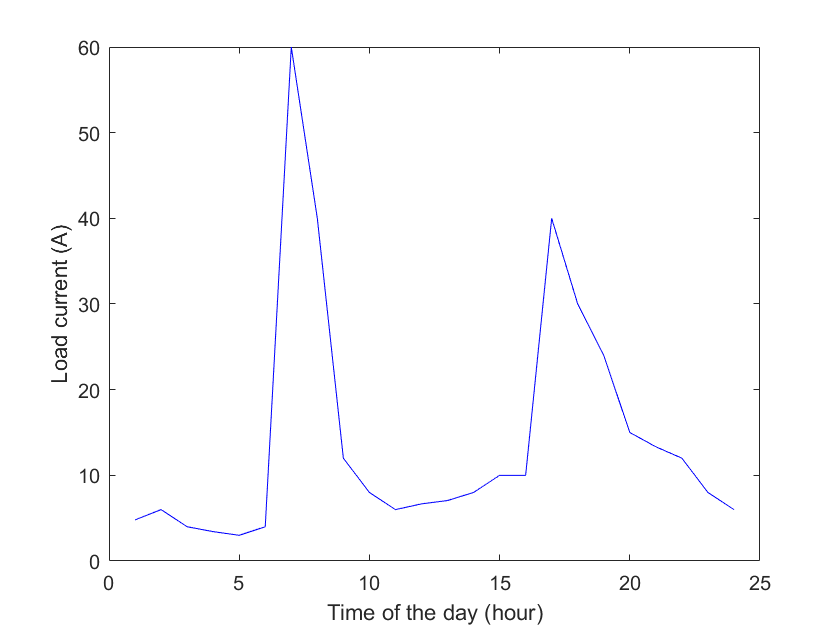

figure(1)
plot(t, I_rms,'b')
hold on
xlabel('Time of the day (hour)'), ylabel('Load current (A)')

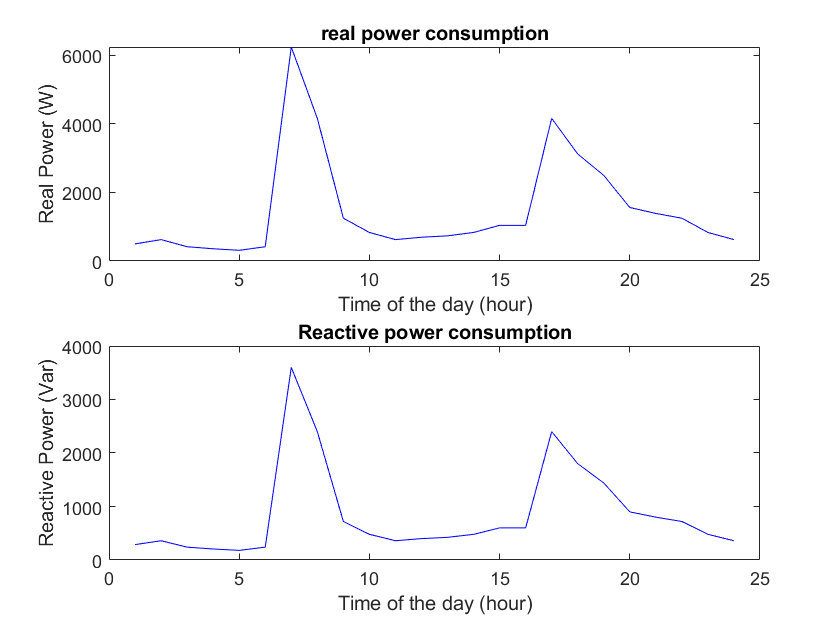


figure(2)
subplot(2,1,1)
plot(t, P,'b')
hold on
xlabel('Time of the day (hour)'), ylabel('Real Power (W)')
title('real power consumption')

subplot(2,1,2)
plot(t, Q,'b')
hold on
xlabel('Time of the day (hour)'), ylabel('Reactive Power (Var)')
title('Reactive power consumption')